# **TP2 : Images sattelites**

clc;
clear;
close all;

Affichage de la vidéo :

V = VideoReader('satellite_video_15_15_oct.avi')

V =   VideoReader with properties:

   General Properties:
            Name: 'satellite_video_15_15_oct.avi'
            Path: 'C:\Users\mathi\OneDrive\Bureau\A faire\Traitement d'image\TP2'
        Duration: 63
     CurrentTime: 0
       NumFrames: 315

   Video Properties:
           Width: 768
          Height: 768
       FrameRate: 5
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


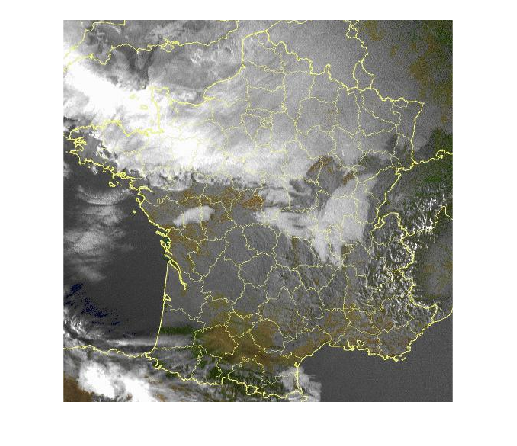

n = input('Enter 1 or 2 (1 to display the video and 2 to pass): ');

switch n
    case 1
        % Lire et afficher les frames de la vidéo
        while hasFrame(V)
            % Lecture d'une frame
            S = readFrame(V);
            
            % Recadrage de la frame
            S = S(150:650, 130:640, :);
            
            % Affichage de la frame recadrée
            imshow(S);
            
            % Pause pour simuler la vitesse de lecture vidéo
            pause(0.001);
        end
        
    case 2
        % Passer à une autre action ou afficher un message
        disp('Case 2 : Aucune action spécifiée.');
        
    otherwise
        % Gestion des cas non valides
        disp('Option invalide. Veuillez choisir une case valide.');
end

Création de référence "ciel clair", on va prendre le pixel le plus faible pour chaque heures :

Dans ce TP, nous allons nous attaquer à un problème essentiel dans l'analyse d'images satellitaires : la suppression des nuages présents dans des séries d'images prises à la même heure sur plusieurs jours. La présence de nuages peut en effet altérer l'interprétation et l'analyse des données géographiques ou climatiques extraites des images satellitaires.

Pour résoudre ce problème, nous mettrons en œuvre une méthode simple mais efficace :

- **Conversion en niveaux de gris** : Les images en couleur (RGB) seront converties en niveaux de gris à l'aide de la fonction MATLAB `rgb2gray`. Cette étape permet de réduire la complexité des données tout en conservant les informations essentielles nécessaires pour identifier les zones couvertes par des nuages.

- **Agrégation par minimisation** : Une fois les images converties, nous utiliserons la fonction MATLAB `min` pour comparer pixel par pixel les intensités de plusieurs images prises à la même heure sur des jours différents. Cette méthode repose sur le fait que les nuages, généralement plus clairs que les autres éléments de l'image (comme la végétation, l'eau ou le sol), peuvent être éliminés en sélectionnant les valeurs minimales d'intensité pour chaque pixel à travers l'ensemble des images.

Au final, cette approche produira une image composite "sans nuages", qui représente les éléments fixes et récurrents de la scène observée, comme le sol, les rivières, ou la végétation. Cette image peut ensuite être utilisée pour des applications telles que la cartographie, l'étude des écosystèmes ou la modélisation climatique.

Im = [];
% for i = 3:10:63
%     for j = 1:7
%         S(i) = read(V,i);
%         Im(j) = S(i);
%         imshow(S)
%         pause(0.1)
%     end
% end

% 7h45 - 18h

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                            %7h45
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Im_1 = read(V,1);
Im_1 = rgb2gray(Im_1);
Im_2 = read(V,21);
Im_2 = rgb2gray(Im_2);
Im_3 = read(V,31);
Im_3 = rgb2gray(Im_3);
Im_4 = read(V,41);
Im_4 = rgb2gray(Im_4);
Im_5 = read(V,51);
Im_5 = rgb2gray(Im_5);
Im_6 = read(V,61);
Im_6 = rgb2gray(Im_6);
Im_7 = read(V,70);
Im_7 = rgb2gray(Im_7);
Im_8 = read(V,79);
Im_8 = rgb2gray(Im_8);
Im_9 = read(V,79);
Im_9 = rgb2gray(Im_9);
Im_10 = read(V,88);
Im_10 = rgb2gray(Im_10);
Im_11 = read(V,97);
Im_11 = rgb2gray(Im_11);
Im_12 = read(V,106);
Im_12 = rgb2gray(Im_12);

for i = 1:768
    for j = 1:768
        % Compute the minimum value across all images at each pixel and channel
        m_Im1(i, j, :) = min([Im_1(i, j, :), Im_2(i, j, :), Im_3(i, j, :), ...
                             Im_4(i, j, :), Im_5(i, j, :), Im_6(i, j, :), Im_7(i,j,:), Im_8(i,j,:), Im_9(i,j,:), ...
                             Im_10(i,j,:), Im_11(i,j,:), Im_12(i,j,:)], [], 2);
    end
end
disp('7h 45')

7h 45


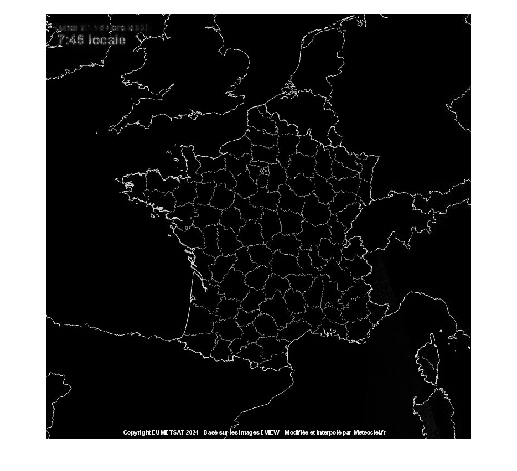

imshow(uint8(m_Im1));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                            %8h45
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Im_1 = read(V,2);
Im_1 = rgb2gray(Im_1);
Im_2 = read(V,22);
Im_2 = rgb2gray(Im_2);
Im_3 = read(V,32);
Im_3 = rgb2gray(Im_3);
Im_4 = read(V,42);
Im_4 = rgb2gray(Im_4);
Im_5 = read(V,52);
Im_5 = rgb2gray(Im_5);
Im_6 = read(V,62);
Im_6 = rgb2gray(Im_6);
Im_7 = read(V,71);
Im_7 = rgb2gray(Im_7);
Im_8 = read(V,80);
Im_8 = rgb2gray(Im_8);
Im_9 = read(V,80);
Im_9 = rgb2gray(Im_9);
Im_10 = read(V,89);
Im_10 = rgb2gray(Im_10);
Im_11 = read(V,98);
Im_11 = rgb2gray(Im_11);
Im_12 = read(V,107);
Im_12 = rgb2gray(Im_12);

for i = 1:768
    for j = 1:768
        % Compute the minimum value across all images at each pixel and channel
        m_Im2(i, j, :) = min([Im_1(i, j, :), Im_2(i, j, :), Im_3(i, j, :), ...
                             Im_4(i, j, :),Im_5(i,j,:),Im_6(i,j,:),Im_7(i,j,:),Im_8(i,j,:),Im_9(i,j,:),Im_10(i,j,:),Im_11(i,j,:),Im_12(i,j,:)], [], 2);
    end
end
disp('8h 45')

8h 45


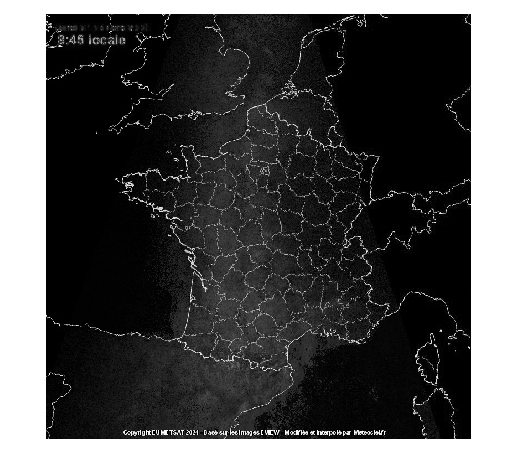

imshow(uint8(m_Im2));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                            %9h45
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Im_1 = read(V,3);
Im_1 = rgb2gray(Im_1);
Im_2 = read(V,23);
Im_2 = rgb2gray(Im_2);
Im_3 = read(V,33);
Im_3 = rgb2gray(Im_3);
Im_4 = read(V,43);
Im_4 = rgb2gray(Im_4);
Im_5 = read(V,53);
Im_5 = rgb2gray(Im_5);
Im_6 = read(V,63);
Im_6 = rgb2gray(Im_6);
Im_7 = read(V,72);
Im_7 = rgb2gray(Im_7);
Im_8 = read(V,81);
Im_8 = rgb2gray(Im_8);
Im_9 = read(V,81);
Im_9 = rgb2gray(Im_9);
Im_10 = read(V,90);
Im_10 = rgb2gray(Im_10);
Im_11 = read(V,99);
Im_11 = rgb2gray(Im_11);
Im_12 = read(V,108);
Im_12 = rgb2gray(Im_12);

for i = 1:768
    for j = 1:768
        % Compute the minimum value across all images at each pixel and channel
        m_Im3(i, j, :) = min([Im_1(i, j, :), Im_2(i, j, :), Im_3(i, j, :), ...
                             Im_4(i, j, :), Im_5(i, j, :), Im_6(i, j, :), Im_7(i,j,:),Im_8(i,j,:),Im_9(i,j,:),Im_10(i,j,:),Im_11(i,j,:),Im_12(i,j,:)], [], 2);
    end
end
disp('9h 45')

9h 45


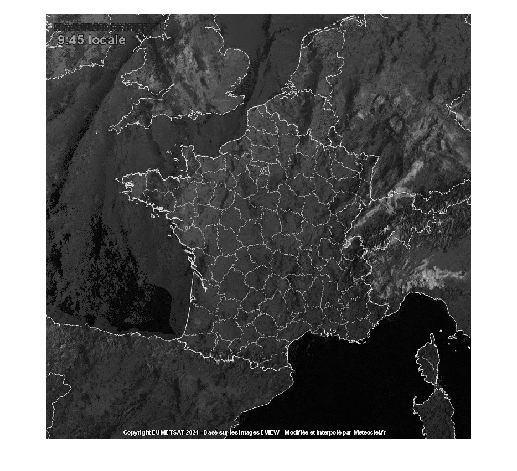


imshow(uint8(m_Im3));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                            %10h45
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Im_1 = read(V,4);
Im_1 = rgb2gray(Im_1);
Im_2 = read(V,24);
Im_2 = rgb2gray(Im_2);
Im_3 = read(V,34);
Im_3 = rgb2gray(Im_3);
Im_4 = read(V,44);
Im_4 = rgb2gray(Im_4);
Im_5 = read(V,54);
Im_5 = rgb2gray(Im_5);
Im_6 = read(V,64);
Im_6 = rgb2gray(Im_6);
Im_7 = read(V,73);
Im_7 = rgb2gray(Im_7);
Im_8 = read(V,82);
Im_8 = rgb2gray(Im_8)

Im_8 = 768×768 uint8 matrix
   180   240   206   177   242   253   234   242   251   252   254   254   254   249   249   249   255   221   253   230   228   221   187   161   170   123   142   131   151   138   171   149   126   144   151   147   143   131   121   124   124   127   167   205   185   137   115   118   122   115
   197   234   230   218   248   253   233   213   254   252   251   252   254   254   254   254   245   218   241   221   190   210   196   188   166   135   153   151   163   154   169   141   129   145   149   143   138   128   123   130   132   152   187   195   158   123   121   130   121   112
   228   229   238   237   235   251   253   226   254   251   249   251   254   255   255   253   252   229   239   222   159   187   180   177   165   153   164   167   160   160   156   129   141   152   150   139   131   121   120   133   160   179   193   171   130   116   122   123   120   110
   244   229   233   234   224   238   253   244   246   250   253   

Im_9 = read(V,82);
Im_9 = rgb2gray(Im_9);
Im_10 = read(V,91);
Im_10 = rgb2gray(Im_10);
Im_11 = read(V,100);
Im_11 = rgb2gray(Im_11);
Im_12 = read(V,109);
Im_12 = rgb2gray(Im_12);

for i = 1:768
    for j = 1:768
        % Compute the minimum value across all images at each pixel and channel
        m_Im4(i, j, :) = min([Im_1(i, j, :), Im_2(i, j, :), Im_3(i, j, :), ...
                             Im_4(i, j, :), Im_5(i, j, :), Im_6(i, j, :), Im_7(i,j,:),Im_8(i,j,:),Im_9(i,j,:),Im_10(i,j,:),Im_11(i,j,:),Im_12(i,j,:)], [], 2);
    end
end
disp('10h 45')

10h 45


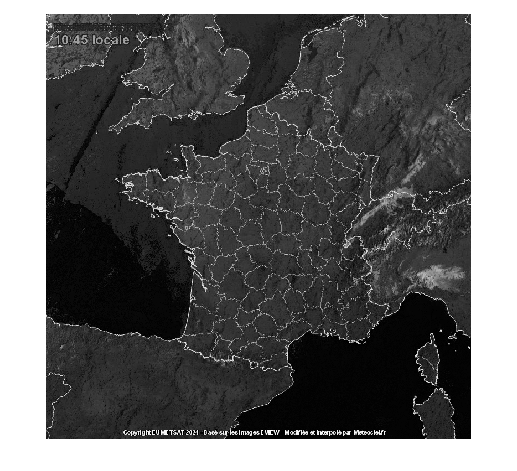

imshow(uint8(m_Im4));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                            %11h45
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Im_1 = read(V,5);
Im_1 = rgb2gray(Im_1);
Im_2 = read(V,25);
Im_2 = rgb2gray(Im_2);
Im_3 = read(V,35);
Im_3 = rgb2gray(Im_3);
Im_4 = read(V,45);
Im_4 = rgb2gray(Im_4);
Im_5 = read(V,55);
Im_5 = rgb2gray(Im_5);
Im_6 = read(V,65);
Im_6 = rgb2gray(Im_6);
Im_7 = read(V,74);
Im_7 = rgb2gray(Im_7);
Im_8 = read(V,83);
Im_8 = rgb2gray(Im_8);
Im_9 = read(V,83);
Im_9 = rgb2gray(Im_9);
Im_10 = read(V,92);
Im_10 = rgb2gray(Im_10);
Im_11 = read(V,101);
Im_11 = rgb2gray(Im_11);
Im_12 = read(V,110);
Im_12 = rgb2gray(Im_12);

for i = 1:768
    for j = 1:768
        % Compute the minimum value across all images at each pixel and channel
        m_Im5(i, j, :) = min([Im_1(i, j, :), Im_2(i, j, :), Im_3(i, j, :), ...
                             Im_4(i, j, :), Im_5(i, j, :), Im_6(i, j, :), Im_7(i,j,:), Im_8(i,j,:), Im_9(i,j,:), ...
                             Im_10(i,j,:), Im_11(i,j,:), Im_12(i,j,:)], [], 2);
    end
end
disp('11h 45')

11h 45


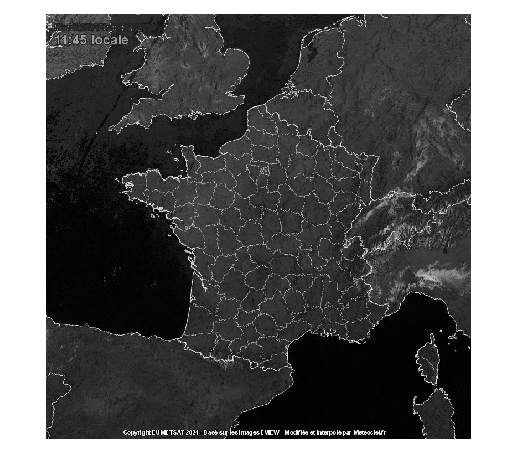

imshow(uint8(m_Im5));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                            %12h45
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Im_1 = read(V,6);
Im_1 = rgb2gray(Im_1);
Im_2 = read(V,26);
Im_2 = rgb2gray(Im_2);
Im_3 = read(V,36);
Im_3 = rgb2gray(Im_3);
Im_4 = read(V,46);
Im_4 = rgb2gray(Im_4);
Im_5 = read(V,56);
Im_5 = rgb2gray(Im_5);
Im_6 = read(V,66);
Im_6 = rgb2gray(Im_6);
Im_7 = read(V,75);
Im_7 = rgb2gray(Im_7);
Im_8 = read(V,84);
Im_8 = rgb2gray(Im_8);
Im_9 = read(V,84);
Im_9 = rgb2gray(Im_9);
Im_10 = read(V,93);
Im_10 = rgb2gray(Im_10);
Im_11 = read(V,102);
Im_11 = rgb2gray(Im_11);
Im_12 = read(V,111);
Im_12 = rgb2gray(Im_12);

for i = 1:768
    for j = 1:768
        % Compute the minimum value across all images at each pixel and channel
        m_Im6(i, j, :) = min([Im_1(i, j, :), Im_2(i, j, :), Im_3(i, j, :), ...
                             Im_4(i, j, :), Im_5(i, j, :), Im_6(i, j, :), Im_7(i,j,:), Im_8(i,j,:), Im_9(i,j,:), ...
                             Im_10(i,j,:), Im_11(i,j,:), Im_12(i,j,:)], [], 2);
    end
end
disp('12h 45')

12h 45


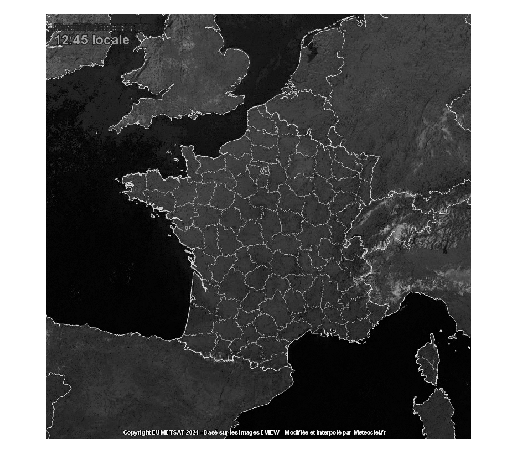

imshow(uint8(m_Im6));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                            %13h45
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Im_1 = read(V,7);
Im_1 = rgb2gray(Im_1);
Im_2 = read(V,27);
Im_2 = rgb2gray(Im_2);
Im_3 = read(V,37);
Im_3 = rgb2gray(Im_3);
Im_4 = read(V,47);
Im_4 = rgb2gray(Im_4);
Im_5 = read(V,57);
Im_5 = rgb2gray(Im_5);
Im_6 = read(V,67);
Im_6 = rgb2gray(Im_6);
Im_7 = read(V,76);
Im_7 = rgb2gray(Im_7);
Im_8 = read(V,85);
Im_8 = rgb2gray(Im_8);
Im_9 = read(V,85);
Im_9 = rgb2gray(Im_9);
Im_10 = read(V,94);
Im_10 = rgb2gray(Im_10);
Im_11 = read(V,103);
Im_11 = rgb2gray(Im_11);
Im_12 = read(V,112);
Im_12 = rgb2gray(Im_12);

for i = 1:768
    for j = 1:768
        % Compute the minimum value across all images at each pixel and channel
        m_Im7(i, j, :) = min([Im_1(i, j, :), Im_2(i, j, :), Im_3(i, j, :), ...
                             Im_4(i, j, :), Im_5(i, j, :), Im_6(i, j, :), Im_7(i,j,:), Im_8(i,j,:), Im_9(i,j,:), ...
                             Im_10(i,j,:), Im_11(i,j,:), Im_12(i,j,:)], [], 2);
    end
end
disp('13h 45')

13h 45


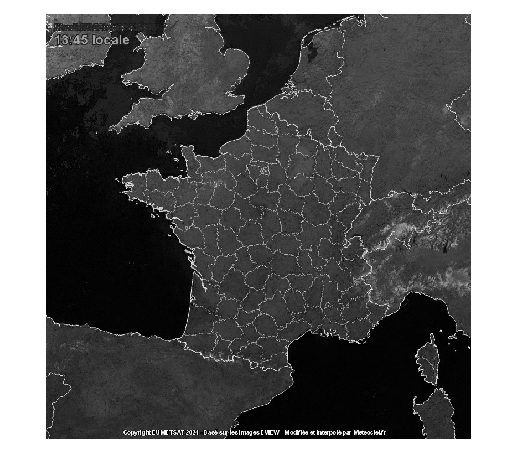

imshow(uint8(m_Im7));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                            %14h45
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Im_1 = read(V,8);
Im_1 = rgb2gray(Im_1);
Im_2 = read(V,28);
Im_2 = rgb2gray(Im_2);
Im_3 = read(V,38);
Im_3 = rgb2gray(Im_3);
Im_4 = read(V,48);
Im_4 = rgb2gray(Im_4);
Im_5 = read(V,58);
Im_5 = rgb2gray(Im_5);
Im_6 = read(V,68);
Im_6 = rgb2gray(Im_6);
Im_7 = read(V,77);
Im_7 = rgb2gray(Im_7);
Im_8 = read(V,86);
Im_8 = rgb2gray(Im_8);
Im_9 = read(V,86);
Im_9 = rgb2gray(Im_9);
Im_10 = read(V,95);
Im_10 = rgb2gray(Im_10);
Im_11 = read(V,104);
Im_11 = rgb2gray(Im_11);
Im_12 = read(V,113);
Im_12 = rgb2gray(Im_12);

for i = 1:768
    for j = 1:768
        % Compute the minimum value across all images at each pixel and channel
        m_Im8(i, j, :) = min([Im_1(i, j, :), Im_2(i, j, :), Im_3(i, j, :), ...
                             Im_4(i, j, :), Im_5(i, j, :), Im_6(i, j, :), Im_7(i,j,:), Im_8(i,j,:), Im_9(i,j,:), ...
                             Im_10(i,j,:), Im_11(i,j,:), Im_12(i,j,:)], [], 2);
    end
end
disp('14h 45')

14h 45


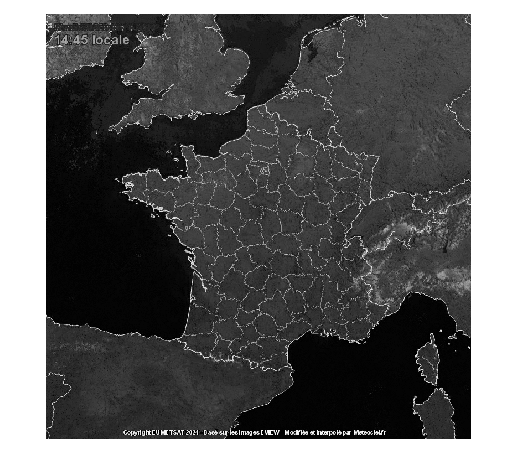

imshow(uint8(m_Im8));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                            %15h45
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Im_1 = read(V,9);
Im_1 = rgb2gray(Im_1);
Im_2 = read(V,29);
Im_2 = rgb2gray(Im_2);
Im_3 = read(V,39);
Im_3 = rgb2gray(Im_3);
Im_4 = read(V,49);
Im_4 = rgb2gray(Im_4);
Im_5 = read(V,59);
Im_5 = rgb2gray(Im_5);
Im_6 = read(V,69);
Im_6 = rgb2gray(Im_6);
Im_7 = read(V,78);
Im_7 = rgb2gray(Im_7);
Im_8 = read(V,87);
Im_8 = rgb2gray(Im_8);
Im_9 = read(V,87);
Im_9 = rgb2gray(Im_9);
Im_10 = read(V,96);
Im_10 = rgb2gray(Im_10);
Im_11 = read(V,105);
Im_11 = rgb2gray(Im_11);
Im_12 = read(V,114);
Im_12 = rgb2gray(Im_12);

for i = 1:768
    for j = 1:768
        % Compute the minimum value across all images at each pixel and channel
        m_Im9(i, j, :) = min([Im_1(i, j, :), Im_2(i, j, :), Im_3(i, j, :), ...
                             Im_4(i, j, :), Im_5(i, j, :), Im_6(i, j, :), Im_7(i,j,:), Im_8(i,j,:), Im_9(i,j,:), ...
                             Im_10(i,j,:), Im_11(i,j,:), Im_12(i,j,:)], [], 2);
    end
end
disp('15h 45')

15h 45


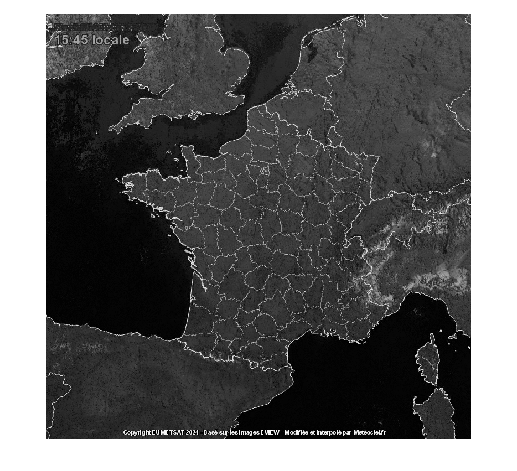

imshow(uint8(m_Im9));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                            %16h45
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Im_1 = read(V,10);
Im_1 = rgb2gray(Im_1);
Im_2 = read(V,30);
Im_2 = rgb2gray(Im_2);
Im_3 = read(V,40);
Im_3 = rgb2gray(Im_3);
Im_4 = read(V,50);
Im_4 = rgb2gray(Im_4);
Im_5 = read(V,60);
Im_5 = rgb2gray(Im_5);
Im_6 = read(V,70);
Im_6 = rgb2gray(Im_6);
Im_7 = read(V,79);
Im_7 = rgb2gray(Im_7);
Im_8 = read(V,88);
Im_8 = rgb2gray(Im_8);
Im_9 = read(V,88);
Im_9 = rgb2gray(Im_9);
Im_10 = read(V,97);
Im_10 = rgb2gray(Im_10);
Im_11 = read(V,106);
Im_11 = rgb2gray(Im_11);
Im_12 = read(V,115);
Im_12 = rgb2gray(Im_12);

for i = 1:768
    for j = 1:768
        % Compute the minimum value across all images at each pixel and channel
        m_Im10(i, j, :) = min([Im_1(i, j, :), Im_2(i, j, :), Im_3(i, j, :), ...
                             Im_4(i, j, :), Im_5(i, j, :), Im_6(i, j, :), Im_7(i,j,:), Im_8(i,j,:), Im_9(i,j,:), ...
                             Im_10(i,j,:), Im_11(i,j,:), Im_12(i,j,:)], [], 2);
    end
end
disp('16h 45')

16h 45


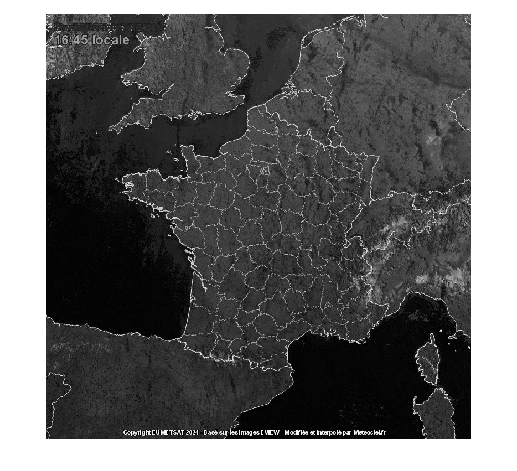

imshow(uint8(m_Im10));

Heure 7h 45
Heure 8h 45
Heure 9h 45
Heure 10h 45
Heure 11h 45
Heure 12h 45
Heure 13h 45
Heure 14h 45
Heure 15h 45


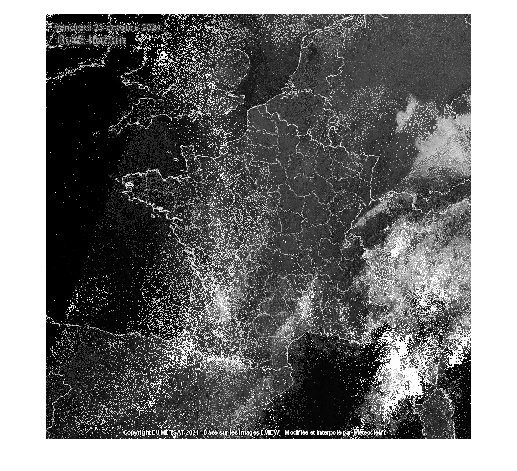

% Dimensions des images
image_size = [768, 768];

% Nombre total de frames
num_frames = 12;

% Préallocation pour m_Im (matrices de résultat)
m_Im = cell(9, 1); % On stocke pour chaque tranche horaire

% Boucle sur les différentes heures
for hour = 1:9
    images = zeros([image_size, num_frames], 'uint8'); % Préallocation pour 12 frames
    
    % Lecture des frames correspondantes pour chaque tranche horaire
    for k = 1:num_frames
        frame_index = (hour - 1) * num_frames + k;
        Im = read(V, frame_index);
        images(:, :, k) = rgb2gray(Im); % Convertir en niveau de gris
    end
    
    % Calcul du mode pixel par pixel
    m_Im{hour} = mode(images, 3);
    
    % Affichage de l'image résultante
    disp(['Heure ', num2str(6 + hour), 'h 45']);
    imshow(uint8(m_Im{hour}));
end

On observe que l'on obtient de moins bons résultats qu'en prenant le pixel minimum entre les différentes images.

Ici, la période d'enregistrement des images était très nuageuse ce qui donne des résultats pas très satisfaisant.